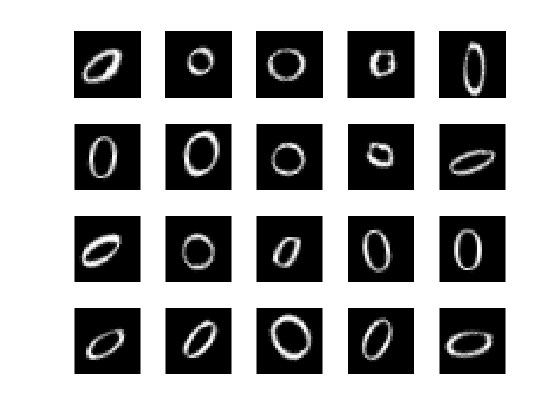

XTrain = digitTrainCellArrayData;

hiddenSize = 20;
autoenc = trainAutoencoder(XTrain,hiddenSize,...
        'L2WeightRegularization',0.004,...
        'SparsityRegularization',4,...
        'SparsityProportion',0.15,...
        'UseGPU', true,...
        'MaxEpoch',500);
    
XTest = digitTestCellArrayData;

xReconstructed = predict(autoenc,XTest);

error=0;

for a = 1:1:5000
    error = error + mse(XTrain{a}-xReconstructed{a});
end

error = error/5000;

figure;
for i = 1:20
    subplot(4,5,i);
    imshow(XTest{i});
end

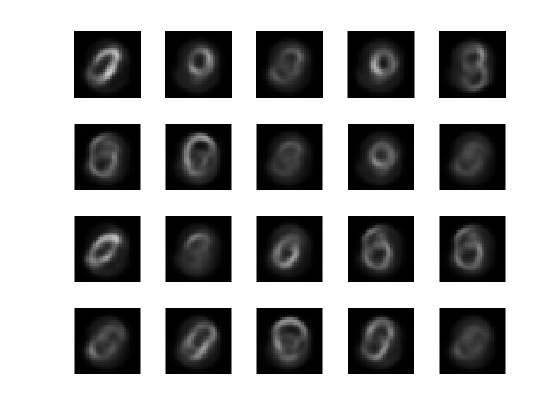


figure;
for i = 1:20
    subplot(4,5,i);
    imshow(xReconstructed{i});
end


disp("Average Mean Squared Error: " + error);

Average Mean Squared Error: 0.04942
